**[01.Esercizi sugli Zeri di Funzione e Metodi Iterativi ad un Passo] - Esercizio 7 **

Dopo aver svolto l'esercizio 7 della dispensa sugli zeri di funzione e i metodi iterativi ad un passo, verifico che i risultati ottenuti siano corretti.

In un file a parte, definisco la *Live Function* che effettua il metodo di Newton modificato, e la chiamo "extra_newton_mod.mlx".

Considero la funzione $f(x)=x^3-x^2-x+1$, con $\alpha$=1, e la sua derivata $df(x)=3x^2-2x-1$.

Faccio il grafico della funzione $f(x)$.

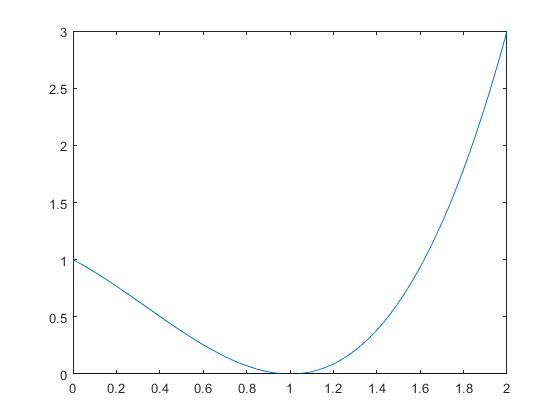

f=@(x) x.^3-x.^2-x+1; %Funzione
df=@(x) 3*x.^2-2*x-1; %Derivata prima
%Grafico
x_mesh=linspace(0,2);%Rete di punti che ci servirà per produrre il grafico
plot(x_mesh,f(x_mesh)) %Questa sarà l'approssimazione del grafico
hold on;
plot([0,2],[0,0],"k") %Asse delle ascisse: plot di ascissa dei punti [0,2] e ordinata dei punti [0,0]

Applico il **metodo di Newton** a $f(x)$.

In base all'esercizio svolto, l'ordine di convergenza atteso è 1, dunque il metodo nello zero specificato si comporta in modo *lineare*.

Imposto una tolleranza di $10^-7$, e come approssimazione dello zero scelgo $0.98$.

x_n=.45;
tol=1e-7;
nitmax=100;

format longe;

[x,nit,res1] = extra_newton_m(f,df,x_n,tol,nitmax)

0	 0.450000000000000	 +4.4e-01
1	 0.789361702127660	 +7.9e-02
2	 0.901267456082580	 +1.9e-02
3	 0.951949688540691	 +4.5e-03
4	 0.976274237788095	 +1.1e-03
5	 0.988208757630841	 +2.8e-04
6	 0.994121913052829	 +6.9e-05
7	 0.997065294639539	 +1.7e-05
8	 0.998533726256486	 +4.3e-06
9	 0.999267132168941	 +1.1e-06
10	 0.999633633258289	 +2.7e-07
11	 0.999816833411834	 +6.7e-08
12	 0.999908420900250	 +1.7e-08
13	 0.999954211498340	 +4.2e-09
14	 0.999977106011279	 +1.0e-09
15	 0.999988553070395	 +2.6e-10
16	 0.999994276552277	 +6.6e-11
17	 0.999997138278562	 +1.6e-11
18	 0.999998569142271	 +4.1e-12
19	 0.999999284574852	 +1.0e-12
20	 0.999999642312206	 +2.6e-13
21	 0.999999821173828	 +6.4e-14
22	 0.999999910574690	 +1.6e-14


x =      9.999999105746895e-01


nit =     22


res1 =      4.386250000000000e-01     7.939128131531548e-02     1.853377424191005e-02     4.506724745240165e-03     1.112468073735773e-03     2.764274167397218e-04     6.890071320841962e-05     1.719971596858549e-05     4.296764953837240e-06     1.073796895734169e-06     2.684000034447465e-07     6.709385280689872e-08     1.677269489963606e-08     4.193077773884113e-09     1.048257369795635e-09     2.620629269145525e-10     6.551548192845758e-11     1.637889823769001e-11     4.094724559422502e-12     1.023736651006857e-12     2.559064071760986e-13     6.394884621840902e-14     1.598721155460225e-14


In effetti, possiamo notare dagli ordini di grandezza dei residui delle varie iterazioni che il metodo non segue un andamento quadratico, come ci si aspetta di solito dal metodo di Newton: *la progressione dell'errore è lineare*.

Proviamo a mostrare graficamente l'ordine di convergenza, tramite un grafico in scala semilogaritmica che riporterà il vettore dei residui.

Sull'asse delle ascisse mettiamo il logaritmo del valore assoluto del residuo dal passo 0 al penultimo passo (nit-1), che noi indicheremo con 1 e end-1. Sull'asse delle ordinate mettiamo gli elementi dello stesso vettore, ma scalati di un indice, quindi da 2 a end.

La pendenza della retta risultante "tradirà" l'ordine di convergenza, e ci permetterà di effettuare una ispezione visuale dell'andamento dell'errore.

figure;
loglog(abs(res1(1:end-1)),abs(res1(2:end)),"x-k") %Vettore dei residui

Inseriamo anche dei valori "indicatori", che ci permetteranno di confrontare l'andamento dell'errore con il tipo di convergenza a cui si avvicina di più.

Queste tre rette sono delle rette di riferimento. Il segmento blu visualizza una convergenza quadratica, quello rosso lineare, quello verde cubica.

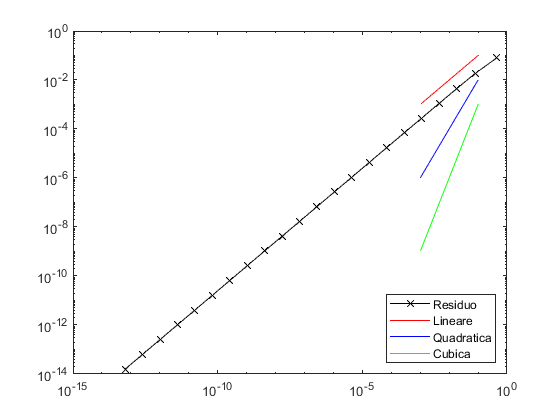

hold on;
loglog([1e-1,1e-3],[1e-1,1e-3], "r") %Convergenza lineare
loglog([1e-1,1e-3],[1e-2,1e-6], "b") %Convergenza quadratica
loglog([1e-1,1e-3],[1e-3,1e-9], "g") %Convergenza cubica
legend("Residuo","Lineare", "Quadratica","Cubica","location","southeast");

Notiamo come la progressione dell'errore sia lineare, e dunque il metodo, per questa funzione e nello zero indicato, avrà **convergenza lineare (o.d.c. = 1)**.

Applico il **metodo di Newton modificato** a $f(x)$.

In base all'esercizio svolto, l'ordine di convergenza atteso è 2, dunque il metodo nello zero specificato si comporta in modo *quadratico*.

Imposto una tolleranza di $10^-7$, e come approssimazione dello zero scelgo $0.45$.

x_n_m=.45;
tol=1e-7;
nitmax=100;

format longe;

[x,nit,res2] = extra_newton_mod(f,df,x_n_m,tol,nitmax)

0	 0.450000000000000	 +4.4e-01
1	 1.128723404255319	 +3.5e-02
2	 1.003777718145742	 +2.9e-05
3	 1.000003557708596	 +2.5e-11
4	 1.000000000001289	 +0.0e+00
5	 1.000000000001289	 +0.0e+00


x =      1.000000000001289e+00


nit =      5


res2 =      4.386250000000000e-01     3.527233970314869e-02     2.859622117612481e-05     2.531463927368804e-11                         0                         0


Nonostante siano state necessarie pochissime iterazioni, possiamo notare come il numero di cifre significative corrette va circa raddoppiando, quindi fa presupporre un andamendo quadratico del metodo modificato.

Proviamo a mostrare graficamente l'ordine di convergenza, tramite un grafico in scala semilogaritmica che riporterà il vettore dei residui.

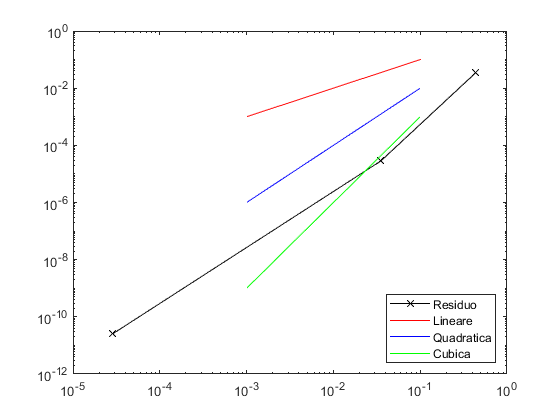

figure;
loglog(abs(res2(1:end-1)),abs(res2(2:end)),"x-k") %Vettore dei residui
hold on;
loglog([1e-1,1e-3],[1e-1,1e-3], "r") %Convergenza lineare
loglog([1e-1,1e-3],[1e-2,1e-6], "b") %Convergenza quadratica
loglog([1e-1,1e-3],[1e-3,1e-9], "g") %Convergenza cubica
legend("Residuo","Lineare", "Quadratica","Cubica","location","southeast");

Notiamo come la progressione dell'errore sia all'incirca quadratica, e dunque il metodo, per questa funzione e nello zero indicato, avrà **convergenza quadratica (o.d.c. = 2)**.